# Control statements: How to use the `for`** loop**?

## Introduction

So far, while writing MATLAB Live Scripts, we’ve been writing commands to be executed one line after another. Unless a line is a comment (denoted by a preceding "`%`"), every line in a script will be executed in order of appearance (sequentially). For example:

x = linspace(0, 1, 100);  % 1st, x is a vector of 100 numbers from 0 to 1
y = x.^2 + 1;             % 2nd, y is a vector of 100 numbers calculated as x.^2+1
plot(x, y);               % 3rd, plots vectors x against y on a graph, and shows it in the Output view
title('Plot of x^2+1');   % 4th, adds a title to the plot
xlabel('x');              % 5th, adds a label to the x-axis
ylabel('y');              % last, adds a label to the y-axis

Fortunately, in MATLAB Live Scripts we can also make use of **control statements**. These are statements (commands) that will allow you to have total control over the **flow** of the code being executed – maybe you only want particular lines executed in particular situations? Or want to repeat a command over and over again?

The flow of the program (live script) can be changed from just executing lines one-by-one, to skipping or repeating intermediate sets of commands.

More technically, control statements are used to modify the order in which commands are executed by MATLAB, so that we are not restricted to executing commands sequentially. MATLAB provides several types of control statements, including

- [if statements](https://au.mathworks.com/help/matlab/ref/if.html), which execute a set of commands if a given condition is satisfied;

- [for loops](https://au.mathworks.com/help/matlab/ref/for.html), which execute a set of commands a given number of times; and

- [while loops](https://au.mathworks.com/help/matlab/ref/while.html), which execute a set of commands while a given condition is true.

In this activity we will learn the basics about how to use `for` loops. In particular we will use `for` loops to calculate and plot terms of sequences defined with a *direct formula* or *recursively*.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

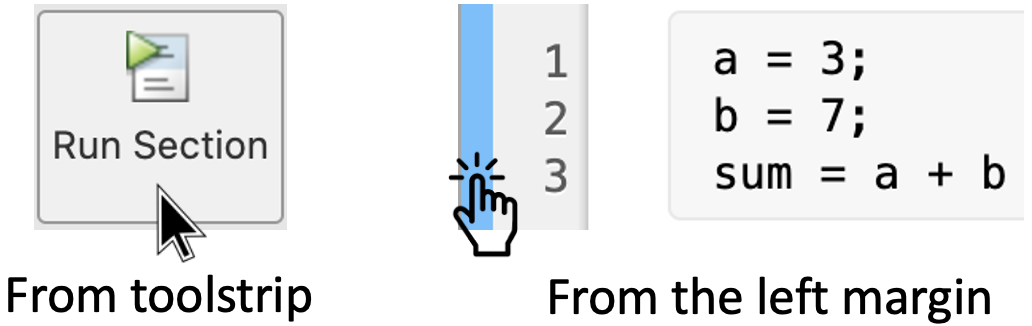

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. The `for` loop

A `for` loop repeatedly executes a set of commands while a variable ranges over a set of values. The general form of a `for` loop is:

The parts of the `for` loop perform the following functions:

- The command `for` tells MATLAB where the loop begins.

- The command `end` tells MATLAB where the loop ends.

- The lines between the `for` and `end` commands are called the body of the loop and contain the commands that will be repeatedly executed by the loop.

- `index_vector` is a vector which determines how many times the commands inside the body of the loop are repeated.

- `index` is a variable that ranges over the elements of `index_vector` during the execution of the loop.

### 1.1 Example 1: Basic use

To see how a `for` loop works, let's look at this basic example:

for k = [1, 2, 3]  

    k^2
     
end  

For this example, the index variable is `k`, the index vector is `[1,2,3]` and there is a single command inside the body of the loop which computes `k^2` and displays it in the Output view (since it is not followed by a semicolon). When the loop is executed, MATLAB performs the following steps:

- Set the index variable `k` equal to 1, the first element of the index vector `[1,2,3]`.

- Execute the first command inside the body, which displays `k^2` in the command window, i.e., $1^2 =1$ is displayed.

- As all commands inside the body of the loop have been executed, return to the beginning of the loop and set `k` equal to 2, the next element in `[1,2,3]`.

- Execute `k^2`, which displays $2^2 =4$ in the command window.

- Return to the beginning of the loop, and set `k` equal to 3, the last element in `[1,2,3]`.

- Execute `k^2`, which displays $3^2 =9$ in the command window.

- Exit the loop as all elements in `[1,2,3]` have been used.

The vector in a `for` loop does not have to be manually entered, as in the above example. Try this yourself by changing the index vector in the above example to each of the following:

- `1:4`, which will produce the same output as before;

- `1:0.5:4`; and

- `[4,7,1,2:5]`.

### 1.2 Example 2: Adding elements of a vector

Consider now the following example, which uses a `for` loop to sum the elements of the vector (1,2,3,4,5,6):

adder = 0;             % First define a variable "adder" starting as 0.
 
for k = 1:6            % From 1 to 6, with an increment of one,
                         
    adder = adder + k  % perform this calculation
                         
end                    % Exit "for" loop


In this case, the *index variable* is `k`, the *index vector* is `[1,2,3,4,5,6]`, which is created by colon notation, and there is a single command inside the loop that adds the value of `k` to the variable `adder`. The variable `adder` acts as a partial sum: it starts out as 0, then the `for` loop adds `k` to it for `k = 1, 2, 3, 4, 5, 6`. The value of `adder` will be displayed 6 times, the number of times the `for` loop is repeated. If you prefer to display only the final result just add the semicolon  "`;`", that is:

`adder = adder + k;`

Then write the variable `adder` outside the `for` loop, right after the `end` command. Try it and re-run this section to see the result!

## 2. Representation of sequences

There are two main ways to represent the *n*-th term in a sequence. Firstly, there is a direct representation (also known as* closed form* or *functional*). Secondly, there is a recursive representation. A direct representation is a formula for $a_n$ in terms of $n$. A recursive description gives a way of obtaining $a_n$ from the previously calculated $a_0 ,a_1 ,\ldotp \ldotp \ldotp ,a_{n-1}$. 

In this context the for loops are very useful to define sequences in both cases. 

### 2.1 Example 1 - Direct representation

For example, consider the sequence defined by the formula:


$$a_n =\frac{n}{n+1}$$


The following code calculates and plots the first 10 terms of this sequence using the [`stem`](https://au.mathworks.com/help/matlab/ref/stem.html) command. These terms will be defined in an array (row vector). To start we need to define a variable:

a = zeros(1,10);    

Here we use the command [`zeros`](https://au.mathworks.com/help/matlab/ref/zeros.html) to create an array of zeros. This is just to improve performance and memory use in MATLAB (You can remove it but you will get a **warning message**).

Now we can use for loop to calculate each term of the sequence: 

for n = 1:10           % From 1 to 10, with an increment of one,
    a(n) = n/(n+1);    % perform this calculation.
end                    % Exit the "for" loop.

stem(a, 'filled');     % Plot all the terms.


**Remark:** *Indexing* is used here to select elements of a vector. In MATLAB, an element of a vector is selected by entering its position in the vector, called its *index*, within brackets `()`. More details here: [Array Indexing](https://au.mathworks.com/help/matlab/math/array-indexing.html).

If you want to know the value of the last term of each sequence, use the code: `a(end)`. Try it yourself! Write this code in the next line after the command `stem`.

### 2.2 Example 2 - Recursive representation

Similarly, we can use a `for` loop to calculate and plot the first 10 terms of the recursive sequence

$b_n =\frac{1}{3-b_{n-1} }$ with $b_1 =2$.

Run this section and analyse carefully the code below:

b = zeros(1,10);          % Pre-allocate zeros in the array to improve performance.

b(1) = 2;                 % Provide the value of the 1st element on the array.
 
for n = 2:10              % From 2 to 10,
    b(n) = 1/(3-b(n-1));  % perform this calculation.
end                       % Exit the "for" loop.

stem(b, 'filled');        % Finally, plot the recursive sequence.


Compare this code with the one from example 2.1. Can you see the main differences? What is the value of the last term of this sequence? That is, what is the value of `b(end)`?

## 3. Hands on practice!

Let's practice what we just learned.

### Fibonacci sequence

The Fibonacci sequence is defined as follows:

$F_1 =1,{\;F}_2 =1$ and $F_i =F_{i-1} +F_{i-2}$ for $i>2$.

Thus, for example,

$F_3 =F_2 +F_1 =1+1=2$,

$F_4 =F_3 +F_2 =2+1=3$,

$F_5 =F_4 +F_3 =3+2=5$.

## Activity 1

Complete the following code to the calculate the *n-*th term of the Fibonacci sequence:

% Set the n-th term of the Fibonacci sequence to calculate. 
% For example, the 5th term with the variable "n"

n = 5;
     
% 1. Create a row vector called "F" containing n zeros.
% This vector will be used to store the terms of the Fibonacci sequence.

%{--Replace this comment with code--}%

% 2. Define the first two terms of the Fibonacci sequence

%{--Replace this comment with code--}%
     
% 3. If i>2, then use the recursive formula
%    to calculate F_3, F_4, ... , F_n.
for i = 3:n
     
    %{--Replace this comment with code--}%
         
end

% 4. Display last value in F.

%{--Replace this comment with code--}%

You can check if your code is correct by comparing the output with the given values.

## Activity 2

Once you figured out how to calculate the *n-*th term of the Fibonacci sequence, plot 50, 100 and 500 terms of this sequence.

Write your code here:

Analise the graph in each case. Adjust the scale with the [`axis()`](https://au.mathworks.com/help/matlab/ref/axis.html#d123e65450) command, if needed.

What do you notice? What do you wonder? Is the Fibonacci sequence convergent or divergent?